% Load and plot the old faithful data set
oldfaithData = dlmread('old_faithful.dat', '\t', 26, 0);
%oldfaithData
x1 = oldfaithData(:,2) % second column 

x1 =    3.600000000000000
   1.800000000000000
   3.333000000000000
   2.283000000000000
   4.533000000000000
   2.883000000000000
   4.700000000000000
   3.600000000000000
   1.950000000000000
   4.350000000000000
   1.833000000000000
   3.917000000000000
   4.200000000000000
   1.750000000000000
   4.700000000000000
   2.167000000000000
   1.750000000000000
   4.800000000000000
   1.600000000000000
   4.250000000000000
   1.800000000000000
   1.750000000000000
   3.450000000000000
   3.067000000000000
   4.533000000000000
   3.600000000000000
   1.967000000000000
   4.083000000000000
   3.850000000000000
   4.433000000000000
   4.300000000000000
   4.467000000000000
   3.367000000000000
   4.033000000000000
   3.833000000000000
   2.017000000000000
   1.867000000000000
   4.833000000000000
   1.833000000000000
   4.783000000000000
   4.350000000000000
   1.883000000000000
   4.567000000000000
   1.750000000000000
   4.533000000000000
   3.317000000000000
   3.833000000000000
   2.100

x2 = oldfaithData(:,3) % third column

x2 =     79
    54
    74
    62
    85
    55
    88
    85
    51
    85
    54
    84
    78
    47
    83
    52
    62
    84
    52
    79
    51
    47
    78
    69
    74
    83
    55
    76
    78
    79
    73
    77
    66
    80
    74
    52
    48
    80
    59
    90
    80
    58
    84
    58
    73
    83
    64
    53
    82
    59
    75
    90
    54
    80
    54
    83
    71
    64
    77
    81
    59
    84
    48
    82
    60
    92
    78
    78
    65
    73
    82
    56
    79
    71
    62
    76
    60
    78
    76
    83
    75
    82
    70
    65
    73
    88
    76
    80
    48
    86
    60
    90
    50
    78
    63
    72
    84
    75
    51
    82
    62
    88
    49
    83
    81
    47
    84
    52
    86
    81
    75
    59
    89
    79
    59
    81
    50
    85
    59
    87
    53
    69
    77
    56
    88
    81
    45
    82
    55
    90
    45
    83
    56
    89
    46
    82
    51
    86
    53
    79
    81
    60
 

figure(1); clf

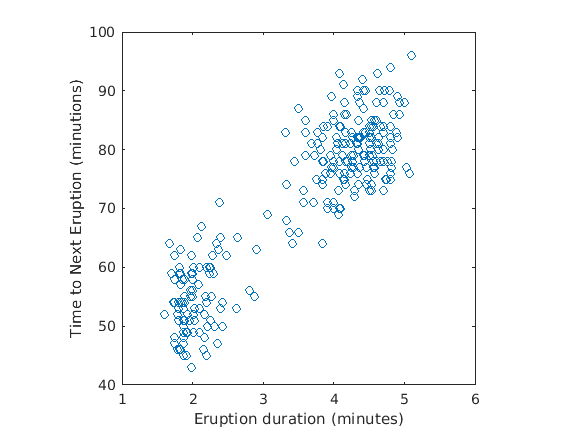

scatter(x1, x2); 
axis square; 
box on
xlabel('Eruption duration (minutes)');
ylabel('Time to Next Eruption (minutions)')

finalMeans = kmeans(3, [x1, x2])

finalMeans =    2.007848484848485  51.257575757575758
   2.667361702127660  63.936170212765958
   4.344610062893082  81.106918238993714


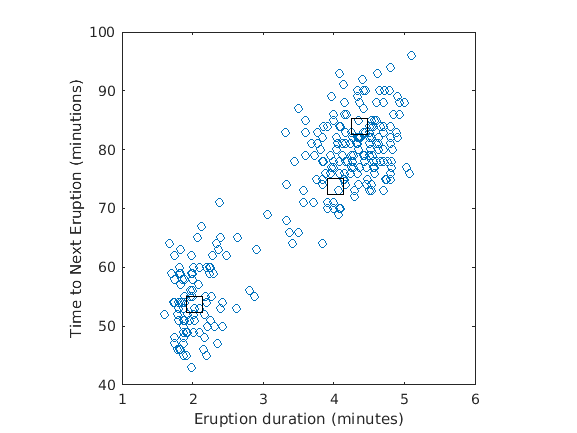

% Plot the final means, adding to previous
figure(1); 
hold on
% here: plotting three groups of 2d vectors (x,y)
plot(finalMeans(:, 1), finalMeans(:, 2), 'ksq', 'markersize', 15)